Anant Mital 

Student # 272484

## Problem 5

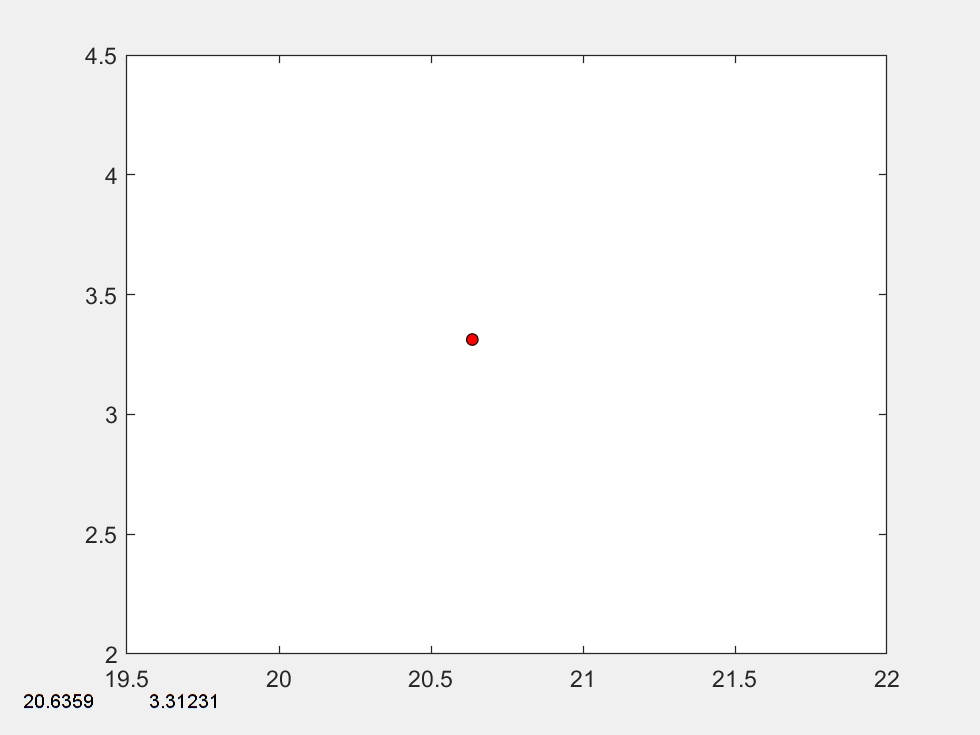

t = 0;
alpha = 0.1;
pd = makedist('Uniform','Lower',0,'Upper',2*pi);
fh = figure('visible','on');
fh.UserData = true;
fh.WindowButtonDownFcn = @(hObject, event) set(hObject, 'UserData', false);
h = plot(t, t, 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 5,'MarkerEdgeColor', 'k');
hx = uicontrol ('Style', 'text', 'Units', 'char' ,'Position',  [1 1 11 1]);
hy = uicontrol ('Style', 'text', 'Units', 'char' ,'Position',  [15 1 11 1]);

dt = 0.0005;
t = t + dt;
while fh.UserData    
    h.XData = h.XData + alpha*(cos(pdf(pd,t)));
    h.YData = h.YData + alpha*(sin(pdf(pd,t)));
    hx.String = h.XData;
    hy.String = h.YData;
    drawnow;
    t = t + dt;
end